# Analisi robusta multivariata, un caso di studio: Real estate dataset.

Il caso di studio consiste nell'analisi previsionale del prezzo dell'unità di superfice di alcune abitazioni della città di Taipei (distretto di Xindian) date le loro caratteristiche attraverso la regressione robusta delle variabili esplicative considerate nel dataset. Il dataset è disponibile sul sito di [Kaggle.com](https://www.kaggle.com/datasets/quantbruce/real-estate-price-prediction).

Questa analisi è permessa dall'utilizzo delle funzioni dell' *FSDA Toolbox* (*Flexible Statistics and Data Analysis*) sviluppato dalla Ro.S.A (*Robust Statistics Academy*) dell'Università degli studi di Parma in collaborazione con il Joint Research Centre della Commissione Europea.

## Indice

-  Introduzione

-  Importazione del dataset e selezione delle variabili.

-  Analsi descrittiva

-  Regressione semplice e robusta.

-  Analisi dei residui ed outliers.

## 1. Introduzione

Il dataset comprende 414 osservazioni e considera le seguenti variabili: la data di acquisto dell'immobile, numeri di anni dalla costruzione dell'immobile, distanza dalla più vicina fermata della metro, numero di minimarket vicini all'abitazione, latitudine, longitudine e prezzo per unità di superficie.

L'analisi del dataset vuole dimostrare come, ed in quale misura, le variabili esplicative $\left.{\left(x\right.}_1 ,x_2 ,\cdots ,x_k \right)$, dette anche regressori, condizionano la variabile dipendente y (prezzo per unità di superficie).

Partendo da un'analisi di tipo descrittivo utilizzando istogrammi e boxplots, si procede con la regressione semplice e robusta dei dati andando a commentare ed evidenziare quelli che sono considerati valori anomali (*outliers*).

## 2. Importazione del dataset e selezione delle variabili.

In questa sezione viene importato il dataset, rinominate le variabili ed eliminata la prima colonna ("*No*") in quanto rappresenta solamente il numero della riga. Utilizzando le apposite funzioni *head* e *tail,* vengono mostrate, come segue, le prime e le ultime 8 righe del set.

clc
close all

tab=readtable("Real_estate.csv","VariableNamingRule","preserve");
tab=renamevars(tab,["X1 transaction date" "X2 house age" "X3 distance to the nearest MRT station" ...
    "X4 number of convenience stores" "X5 latitude" "X6 longitude" "Y house price of unit area"], ...
    ["Transaction date" "House age" "Distance to the nearest MRT station" ...
    "Number of convenience store" "Latitude" "Longitude" "House price of unit area"]);
tab=removevars(tab,"No");

y=tab{:,"House price of unit area"};
X=tab{:,["House age" "Distance to the nearest MRT station" "Number of convenience store"]};

disp('Prime 8 righe');

Prime 8 righe


disp(head(tab));

    Transaction date    House age    Distance to the nearest MRT station    Number of convenience store    Latitude    Longitude    House price of unit area
    ________________    _________    ___________________________________    ___________________________    ________    _________    ________________________

         2012.9             32                     84.879                               10                  24.983      121.54                37.9          
         2012.9           19.5                     306.59                                9                   24.98      121.54                42.2          
         2013.6           13.3                     561.98                                5                  24.987      121.54       

disp('Ultime 8 righe');

Ultime 8 righe


disp(tail(tab));

    Transaction date    House age    Distance to the nearest MRT station    Number of convenience store    Latitude    Longitude    House price of unit area
    ________________    _________    ___________________________________    ___________________________    ________    _________    ________________________

         2013.2            1.9                     372.14                                7                  24.973      121.54                40.5          
           2013            5.2                       2409                                0                  24.955      121.56                22.3          
         2013.4           18.5                     2175.7                                3                  24.963      121.51       

## 3. Analisi descrittiva

### Histogram

Viene utilizzata la funzione *histogram* per visualizzare le variabili *House age, Distance to the nearest MRT station, Number of convenience store *e *Price. *Essa si configura come una rappresentazione grafica costituita da più rettangoli adiacenti (*bins*), ognuno dei quali ha per base un certo intervallo della variabile e un'altezza tale che la sua area rappresenti, nella scala prefissata, il relativo valore globale della funzione.

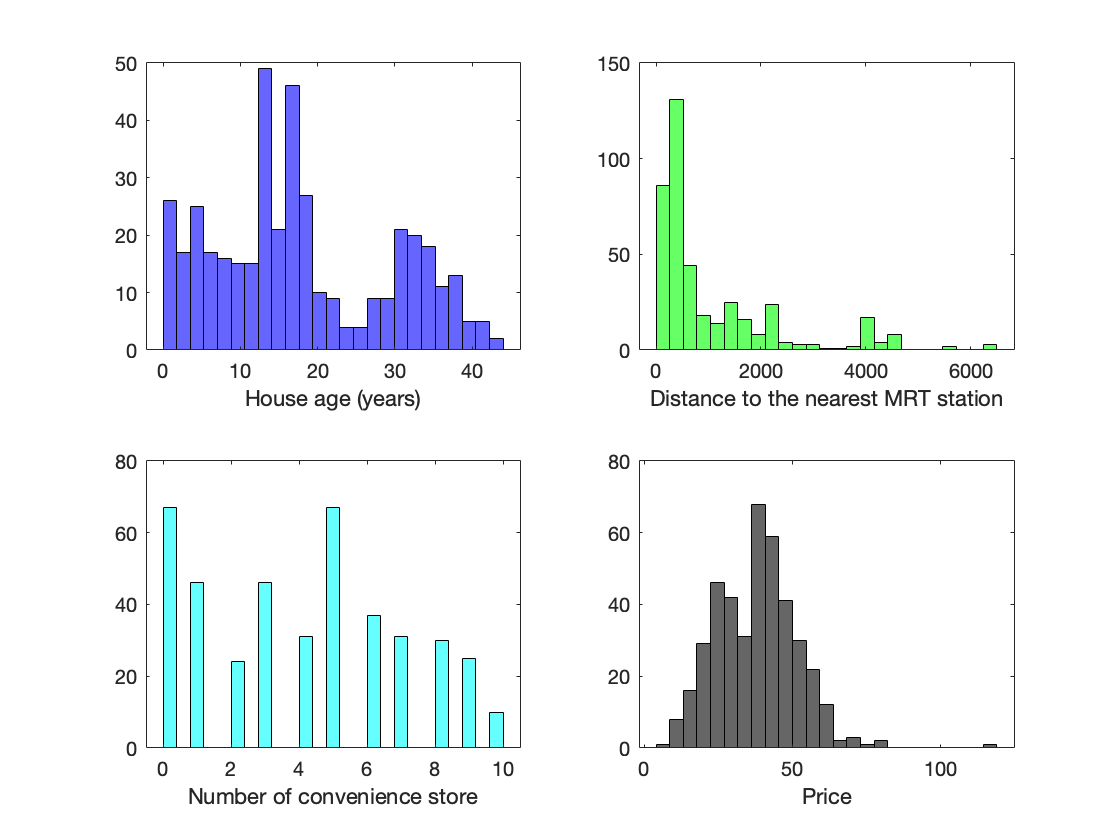

figure
subplot(2,2,1)
histogram(X(:,1),25,FaceColor='b')
xlabel('House age (years)')

subplot(2,2,2)
histogram(X(:,2),25,FaceColor='g')
xlabel('Distance to the nearest MRT station')

subplot(2,2,3)
histogram(X(:,3),25,FaceColor='c')
xlabel('Number of convenience store')

subplot(2,2,4)
histogram(y,25,FaceColor='k')
xlabel('Price')

Dagli istogrammi è possibile vedere in quale range di valori si distribuiscono maggiormente le diverse variabili. Di conseguenza, la variabile *House age* presenta 49 valori nell'intervallo [12,32 14,08]; *Distance to the nearest MRT station* presenta 131 valori nell'intervallo [260 520]; *Number of convenience store* mostra due gruppi principali da 67 valori negli intervalli [0 0.4] e [4,8 5,2]; infine, la variabile *Price* presenta la consueta distribuzione *Normale *(*Gaussiana*) con 68 valori nell'intervallo [36,2 40,8] e presenta un valore anomalo estremamente grande (117.5). 

### Boxplot

Viene utilizzata la funzione* boxplot* per osservare quali valori per ciascuna variabile possano essere considerati anomali (o presunti tali). Il boxplot è un grafico caratterizzato da quattro elementi principali:

- Un segmento che indica la posizione della *mediana* della distribuzione,

- Un rettangolo (*box*) la cui lunghezza indica il grado di dispersione del 50% dei valori centrali della distribuzione che si identificano come i valori compresi nella *distanza interquartile* ossia la differenza tra il terzo ed il primo quartile.

- Due segmenti che, partendo dai lati minori del *box*, indicano fino a che valore si estendono le code (destra e sinistra) della distribuzione escludendo i presunti valori *anomali*.

- Eventuali valori esterni considerati *anomali*. 

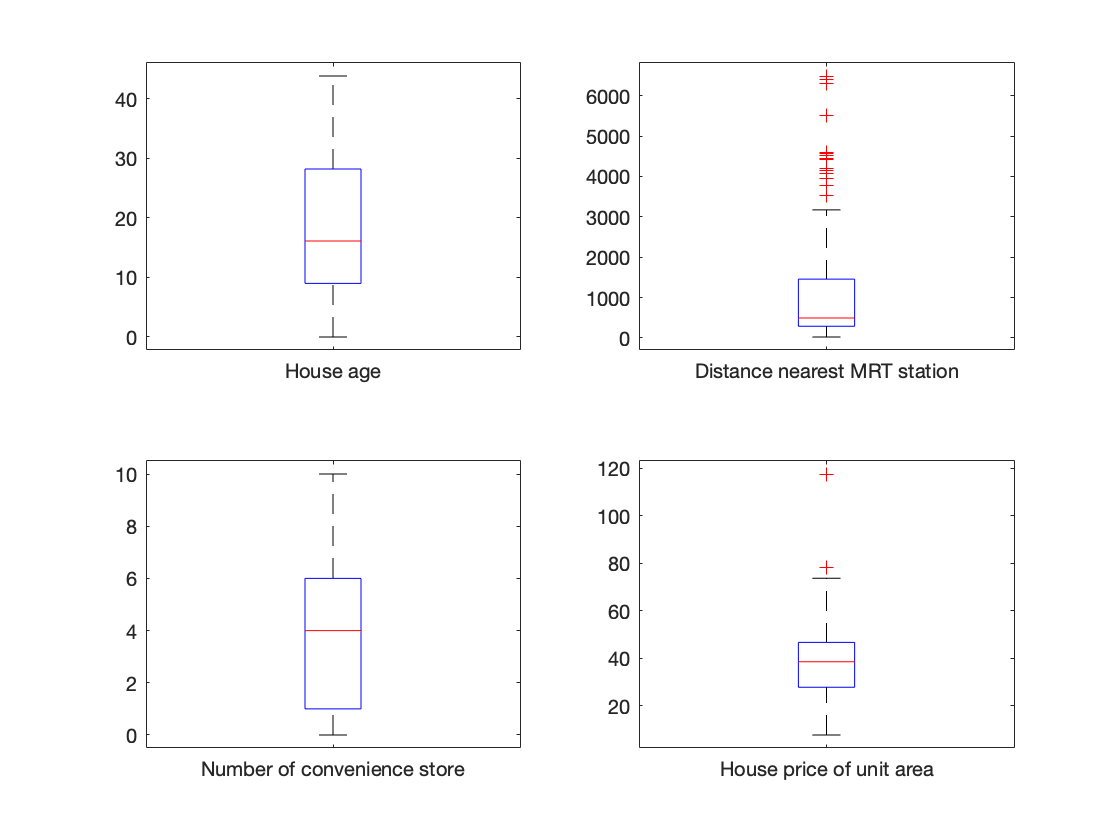

figure("Name","Boxplots")
subplot(2,2,1)
boxplot(tab.("House age"),"Labels","House age")
subplot(2,2,2)
boxplot(tab.("Distance to the nearest MRT station"),"Labels","Distance nearest MRT station")
subplot(2,2,3)
boxplot(tab.("Number of convenience store"),"Labels","Number of convenience store")
subplot(2,2,4)
boxplot(tab.("House price of unit area"),"Labels","House price of unit area")

Come si evince dai 4 boxplots, le variabili *House age* e *Number of convenience store* non presentano particolari valori anomali presentando rispettivamente invece mediana di valore 16,1 e 4. Le variabili *Distance nearest MRT station *e* House price of unit area *presentano nel primo caso mediana uguale a 492,2313 e numerosi valori anomali di grande valore posizionati nell'intervallo [3529,564  6488,021], mentre nel secondo caso la mediana è uguale a 38,45 e si notano due valori anomali, uno molto vicino alla coda destra (78,3) ed uno, invece, molto distante (117,5).

### Correlation Matrix

La *matrice di correlazione *(*corrplot*) indica i coefficienti di correlazione di tutte le coppie di variabili nella matrice input. Ogni *subplot *al di fuori della diagonale contiene uno *scatterplot* di una specifica coppia di variabili a cui viene associata una linea di riferimento basata sui minimi quadrati (retta di regressione), mentre ogni subplot sulla diagonale rappresenta un istogramma della distribuzione della variabile. Ogni coefficiente di correlazione lineare [-1 1] è ottenuto calcolando la *covarianza* calcolata sugli scostamenti standardizzati secondo la formula:


$$r_{\textrm{xy}} =\frac{\textrm{COV}\left(X,Y\right)}{\sqrt{\textrm{VAR}\left(X\right)\textrm{VAR}\left(Y\right)}}$$
 

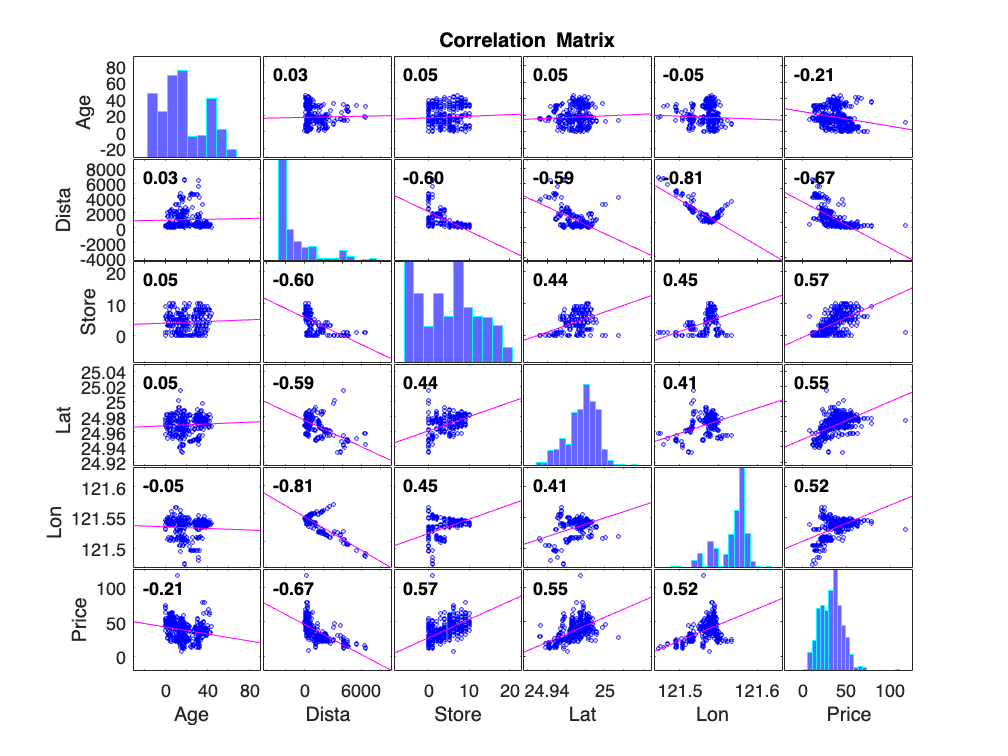

varnames={'Age' 'Distance MRT' 'Store' 'Lat' 'Lon' 'Price'};
figure
[R,PValue]=corrplot(tab{:,2:7},'varnames',varnames);

Nella matrice in considerazione notiamo sia relazioni negative ($r_{\textrm{xy}} <0$), sia positive ($r_{\textrm{xy}} >0$), sia tendenti a valori prossimi a 0 esprimendo una non correlazione.

### Geoplot

La funzione *geoplot* crea una cartina geografica, basata su latitudine e longitudine, che permette di identificare le osservazioni (abitazioni) su una mappa geografica. Il grafico è utile per analizzare se la posizione più o meno centrale in una determinata città (nel nostro caso Taipei) possa influenzare il prezzo per unità di superficie. In questo caso, la maggioranza delle abitazioni si trova nel centro del distretto di Xindian ed, osservando la matrice di correlazione tra prezzo/latitudine e tra prezzo/longitudine, si può notare come al crescere della longitudine si verifichi un aumento del prezzo così come per la latitudine; infatti, all'aumentare delle due variabili ci si sposta verso il centro del distretto.

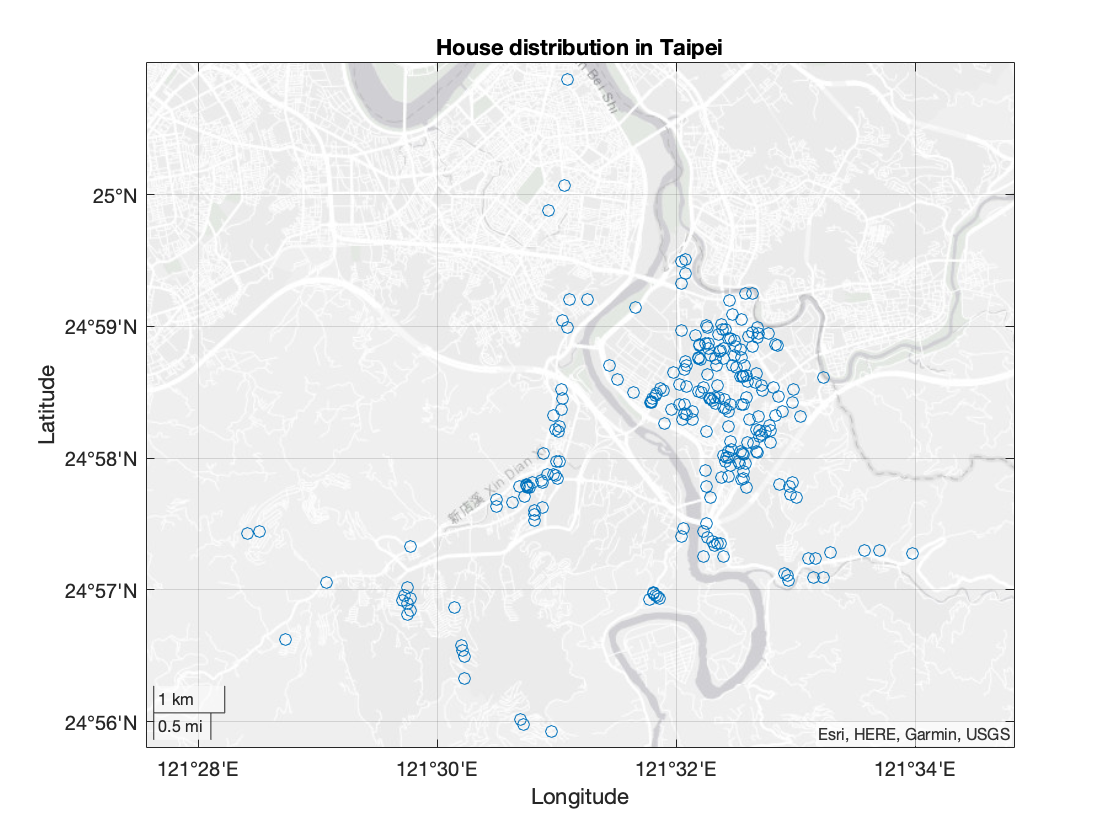

figure('Name','House distribution in Taipei')
geoplot(tab.Latitude,tab.Longitude,"o");
geobasemap streets-light
title('House distribution in Taipei')

## 4. Regressione semplice e robusta.

Tramite i modelli di regressione è possibile capire se ciascun valore osservato dalla variabile dipendente sia esprimibile come funzione lineare del corrispondete valore della variabile esplicativa (indipendente) più un residuo che mostra l'incapacità del modello di riprodurre con esattezza la realtà. Date *n* coppie di osservazioni dei valore ($x_i \;,x_j$) di due fenomeni quantitativi *X* ed *Y *, la regressione lineare è esprimibile da una retta con equazione:


$$y_i =a+{b\;x}_i +e_i \;\;\;\;\;\;\;\;\textrm{con}\;i=1,2,\cdots ,n$$


dove:

- $y_i$ ed $x_i$ sono valori della variabile dipendente e della variabile idipendente

- $a$ è l'intercetta della retta di regressione con l'asse $y$ (punto di origine)

- $b$è il coefficinete angolare (o *di regressione*).

- $e_i$ è il *residuo*.

La funzione lineare dei valori $x_{i\;}$rappresenta la retta di regressione:


$$\hat{y_i } =a+b\;x_i \;\;\;\;\;\;\;\;\textrm{con}\;i=1,2,\cdots ,n$$


dove l'intercetta $a$ è il valore che assume ${\hat{y} }_i$ quando *X* è pari a 0, mentre i residui sono considerati come la differenza tra i valori teorici ${\hat{y} }_i$ ed i valori osservati $y_i$. Di seguito viene eseguito il modello di regressione semplice tra il prezzo dell casa per unità di superficie e le tre principali variabili indipendenti: *House age, Distance to the nearest MRT station *e *Number of convenience store.*

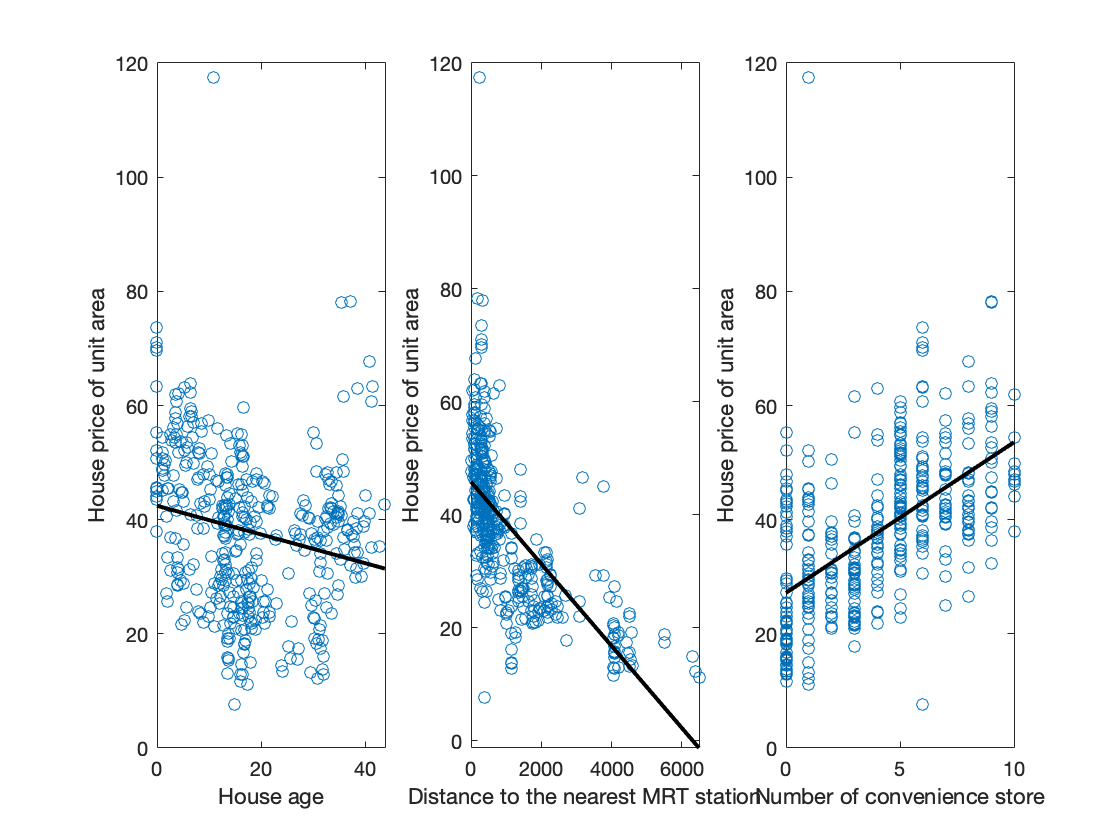

figure("Name", "Regressione semplice")
subplot(1,3,1)
plot(tab.("House age"),y,"o")
ls1=lsline;
ls1.Color='k';
ls1.LineWidth=2;
xlabel("House age")
ylabel("House price of unit area")

subplot(1,3,2)
plot(tab.("Distance to the nearest MRT station"),y,"o")
ls2=lsline;
ls2.Color='k';
ls2.LineWidth=2;
xlabel("Distance to the nearest MRT station")
ylabel("House price of unit area")

subplot(1,3,3)
plot(tab.("Number of convenience store"),y,"o")
ls3=lsline;
ls3.Color='k';
ls3.LineWidth=2;
xlabel("Number of convenience store")
ylabel("House price of unit area")

Date le rette di regressione semplici, si osserva come varia la regressione andando ad utilizzare le rette di regressione robusta, le quali non considerano eventuali "*outliers*".

figure("Name", "Regressione semplice e robusta")

subplot(1,3,1)
plot(tab.("House age"),y,"o")
ls1=lsline;
ls1.Color='k';
ls1.LineWidth=2;
[outLTSage]=LXS(y,tab.("House age"));

Total estimated time to complete LMS:  0.08 seconds 


b = outLTSage.beta;
hold('on')
plot(tab.("House age"),b(1)+b(2)*tab.("House age"), 'r','LineWidth' ,1.5);
legend({'Points' 'Least squares fit' 'Robust fit'},'Location','best');
xlabel("House age")
ylabel("House price of unit area")

subplot(1,3,2)
plot(tab.("Distance to the nearest MRT station"),y,"o")
ls2=lsline;
ls2.Color='k';
ls2.LineWidth=2;
[outLTSmrt]=LXS(y,tab.("Distance to the nearest MRT station"));

Total estimated time to complete LMS:  0.11 seconds 


b = outLTSmrt.beta;
hold('on')
plot(tab.("Distance to the nearest MRT station"),b(1)+b(2)*tab.("Distance to the nearest MRT station"), 'r','LineWidth' ,1.5);
legend({'Points' 'Least squares fit' 'Robust fit'},'Location','best');
xlabel("Distance to the nearest MRT station")
ylabel("House price of unit area")

subplot(1,3,3)
plot(tab.("Number of convenience store"),y,"o")
ls3=lsline;
ls3.Color='k';
ls3.LineWidth=2;
[outLTSmrt]=LXS(y,tab.("Number of convenience store"));

Total estimated time to complete LMS:  0.12 seconds 


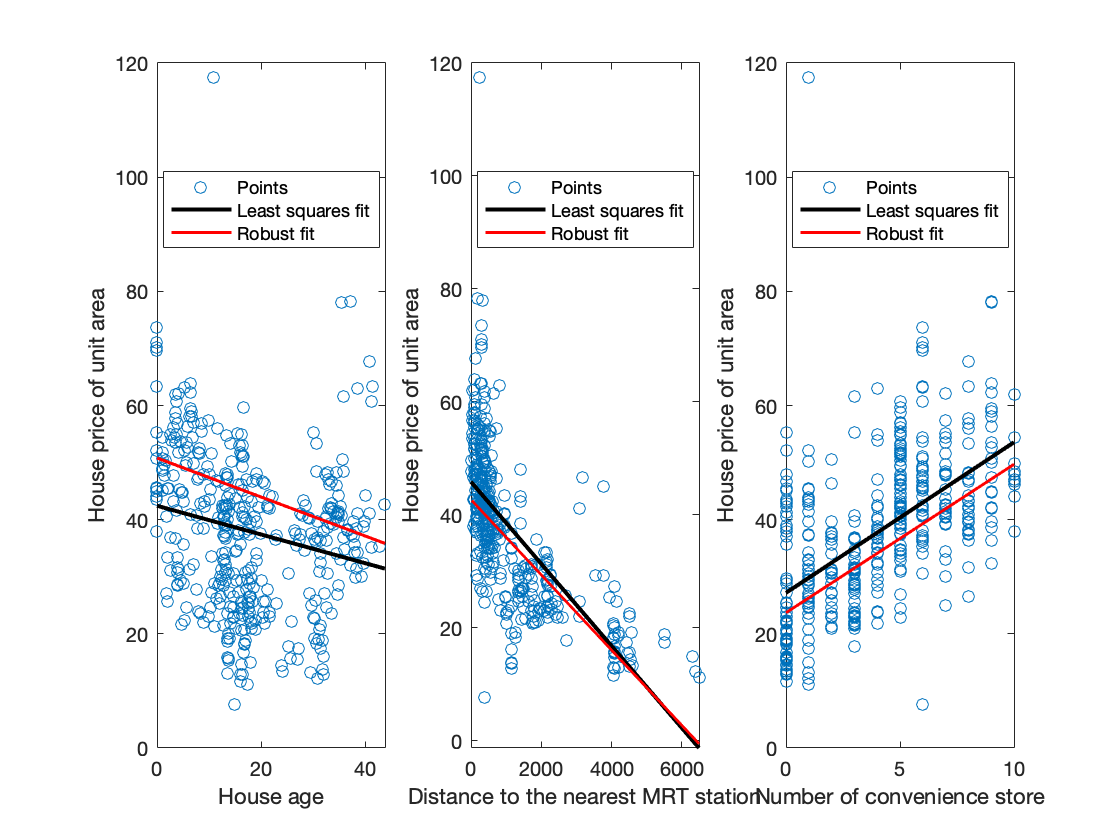

b = outLTSmrt.beta;
hold('on')
plot(tab.("Number of convenience store"),b(1)+b(2)*tab.("Number of convenience store"), 'r','LineWidth' ,1.5);
legend({'Points' 'Least squares fit' 'Robust fit'},'Location','best');
xlabel("Number of convenience store")
ylabel("House price of unit area")

Come osservabile dai grafici la retta di regressione robusta non varia molto la precisione del modello. Tramite la funzione *yXplot*  possiamo visualizzare le tre variabili indipendenti contro la variabile dipendente.

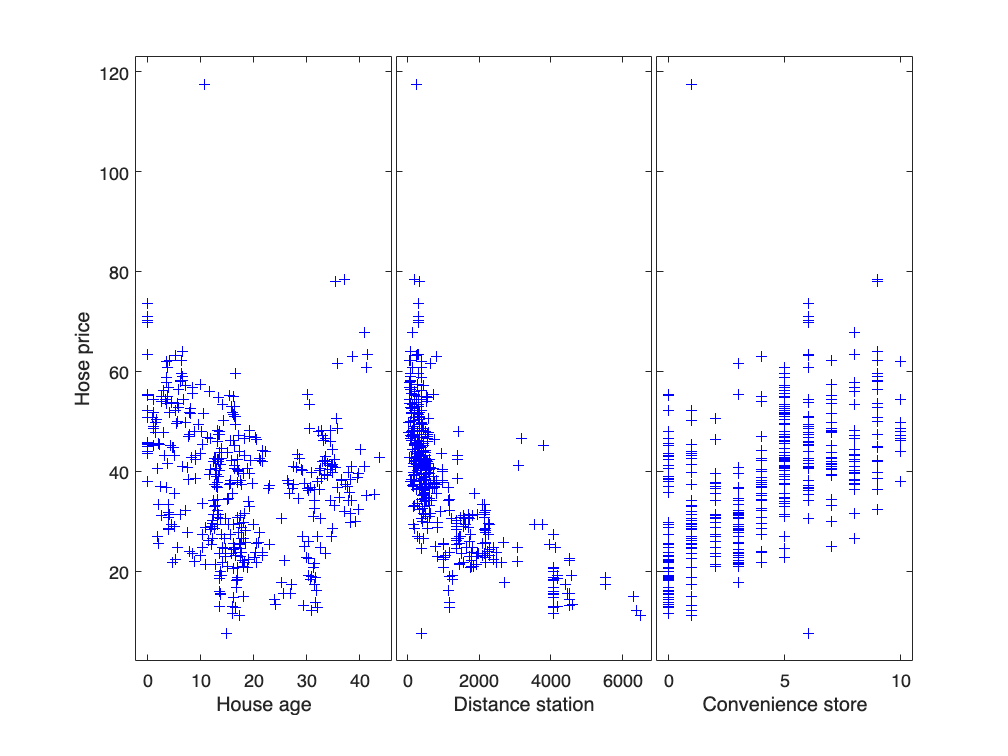

yXplot(y,X,'nameX',{'House age' 'Distance station' 'Convenience store'},'namey',{'Hose price'});
legend off

I grafici ci permettono di osservare come sono posizionati i valori nella loro relazione con la variabile dipendente. Nel primo grafico (*House age*) notiamo come si formino due distinti gruppi divisi da un valore di *x* prossimo al 23. Nel secondo grafico (*Distance to the nearest MRT station*) osserviamo una grande quantità di valori vicini a valori compresi tra 0 e 2000, andando a delineare una relazione negativa tra le due variabili. Nel terzo ed ultimo grafico (*Number of convenience store*) osserviamo una leggera relazione positiva tra il numero di discount ed il valore della casa. Tutti e tre i grafici mostrano un evidente valore anomalo nella parte superiore del grafico.

Per verificare la bontà di adattamento del modello ed il relativo p-value si utilizza la funzione *fitlm*.

out=fitlm(X,y);
disp(out)

Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                    Estimate         SE         tStat       pValue   
                   __________    __________    _______    ___________

    (Intercept)        42.977        1.3845     31.041    1.0856e-109
    x1               -0.25286      0.040105    -6.3048     7.4705e-10
    x2             -0.0053791    0.00045303    -11.874     3.7641e-28
    x3                 1.2974       0.19429     6.6779     7.9085e-11


Number of observations: 414, Error degrees of freedom: 410
Root Mean Squared Error: 9.25
R-squared: 0.541,  Adjusted R-Squared: 0.538
F-statistic vs. constant model: 161, p-value = 5.44e-69


La funzione fornisce una bontà di adattamento $R^2 =0\ldotp 541$ ed un $p-\textrm{value}=5\ldotp 44e-69$. Il primo indica che il modello spiega il 54,1% della variabilità del prezzo delle case per unità di superficie, mentre il p-value la significatività del test e che per valori inferiori generalmente a 0,05 permette di evidenziare una fortissima relazione lineare tra le variabili.

È opportuno trasformare i dati in modo tale da ottenere una bontà di adattamento maggiore. Per trasformare i dati è opportuno calcolare i vari valori di *Lambda* ($\Lambda$) la quale è definita come misura della varianza percentuale nelle variabili dipendenti non spiegata dalle differenze nei livelli della variabile dipendente.

Quindi:

out=Score(y,X);
lam="lambda="+([-1:0.5:1]');
disp(array2table(out.Score,'RowNames',lam,"VariableNames","Score test"));

                   Score test
                   __________

    lambda=-1        25.589  
    lambda=-0.5      13.923  
    lambda=0         4.2308  
    lambda=0.5      -4.9648  
    lambda=1        -14.329  



Trovati i valori di Lambda, la funzione *FSRfan* permette di monitorare i valori dei *Test Statistici* per ogni lambda ottenendo:

Total estimated time to complete LMS:  0.11 seconds 
Total estimated time to complete LMS:  0.03 seconds 
Total estimated time to complete LMS:  0.06 seconds 
Total estimated time to complete LMS:  0.05 seconds 
Total estimated time to complete LMS:  0.09 seconds 


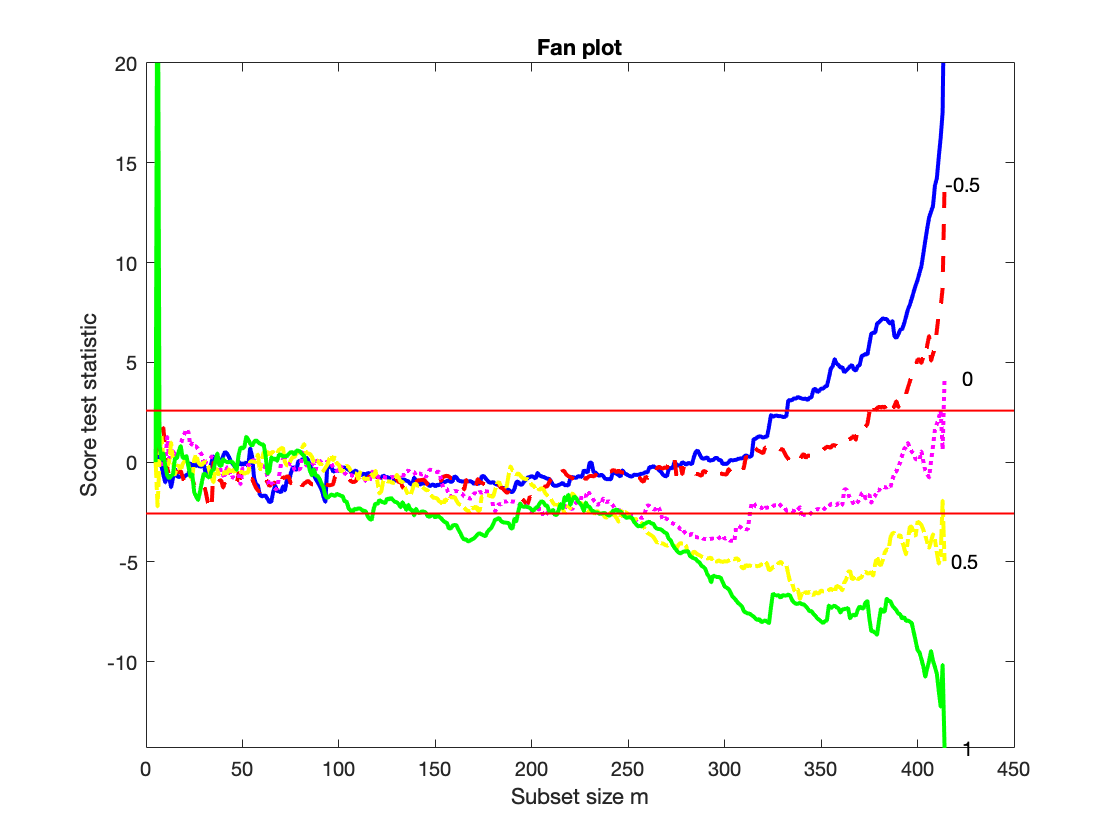

[outfan]=FSRfan(y,X,'plots',1,'init',5);

In particolare, con la funzione *fanBIC* è possibile identificare il miglior valore di Lamba con cui procedere alla trasformazione dei dati.

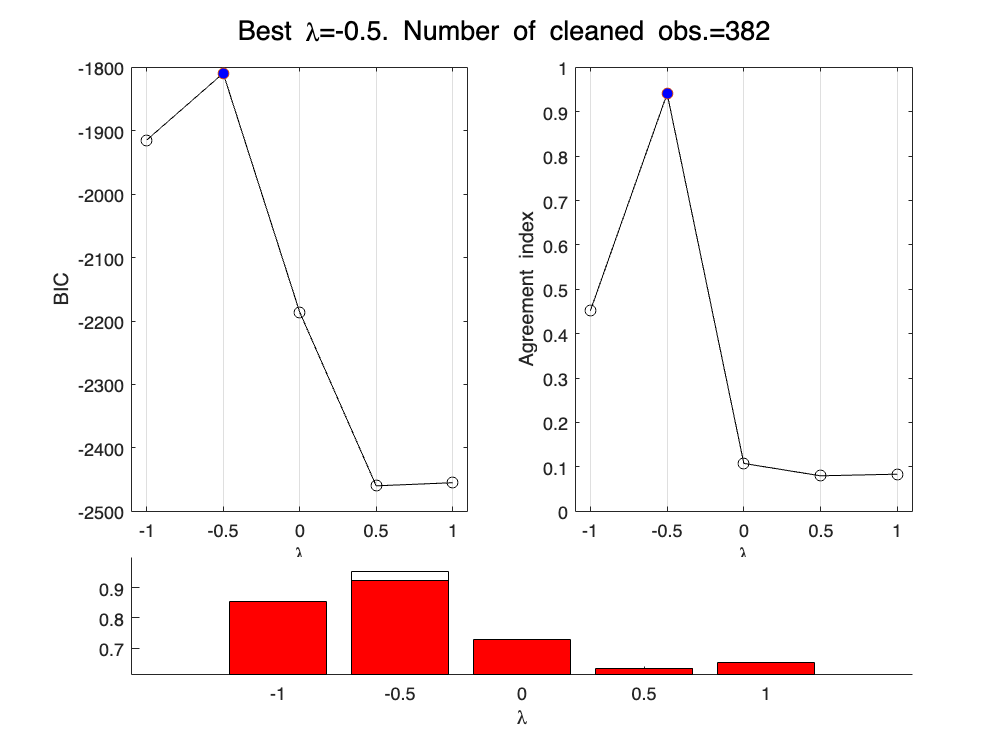

n=length(y);
[out]=fanBIC(outfan);

In questo caso il valore migliore di Lambda è -0.5, quindi:


$$y=y^{-0\ldotp 5}$$


y1=y.^-0.5;
n=length(y);

Si osserva la variazione dell' *yXplot *procedendo nuovamente con la funzione *fitlm.*

yXplot(y1,X,'nameX',{'House age' 'Distance station' 'Convenience store'},'namey',{'Hose price'})

ans =   1×3 Line array:

    Line    Line    Line


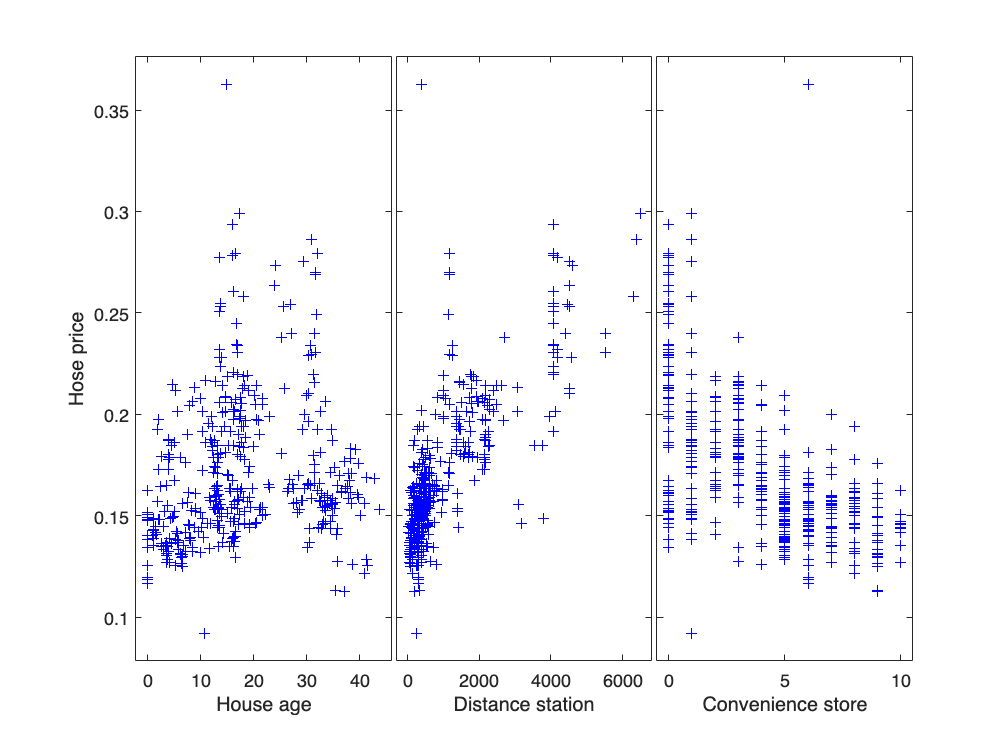

legend off

out=fitlm(X,y1);
disp(out)

Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                    Estimate         SE         tStat       pValue   
                   __________    __________    _______    ___________

    (Intercept)        0.1531      0.003321     46.102    2.6655e-164
    x1             0.00053285    9.6197e-05     5.5391     5.4439e-08
    x2             1.8178e-05    1.0867e-06     16.728     2.9389e-48
    x3             -0.0026264    0.00046603    -5.6358     3.2462e-08


Number of observations: 414, Error degrees of freedom: 410
Root Mean Squared Error: 0.0222
R-squared: 0.632,  Adjusted R-Squared: 0.629
F-statistic vs. constant model: 235, p-value = 1.31e-88


Trasformando i dati otteniamo una bontà di adattamento maggiore $R^2 =0\ldotp 632$ ed un valore di $p-\textrm{value}=1\ldotp 31e-88$. Il modello ora spiega il 63,2% della variabilità del prezzo delle case per unità di superficie con un *p-value* inferiore.

##  5. Analisi dei residui ed outliers.

Questa sezione va ad analizzare gli outliers tramite i metodi di identificazione automatica e di analisi.

Tramite le proprietà della funzione *fitlm* è possibile andara a ricavare i residui. Una volta individuati è possobile costruire il *qqplotFS *(quantile-quantile plot). Esso visualizza i quantili dei dati del campione rispetto ai valori quantilici teorici da una distribuzione normale. Se il campione è distribuito normalmente il risultato risulta una retta.

outLM=fitlm(X,y1,'exclude','');
res=outLM.Residuals{:,3};
qqplot(res)

qqplotFS(res,'X',X,'plots',1);
title('qqplot of stud. res.')

Le bande (envelopes) sono formate da una matrice con due colonne corrispondenti ai valori di confidenza rispettivamente inferiori e superiori. È di conseguenza possibile identificare automaticamente i valori anomali utilizzando la funzione *FSR*.

[outFSR]=FSR(y.^-0.5,X,'init',7);

Observed curve of r_min is at least 10 times greater than 99.99% envelope
--------------------------------------------------
-------------------------
Signal detection loop
Tentative signal in central part of the search: step m=339 because
rmin(339,414)>99.99% and rmin(338,414)>99.99% and rmin(340,414)>99.99%

-------------------
Signal validation exceedance of upper envelopes
Validated signal
-------------------------------
Start resuperimposing envelopes from step m=338
Superimposition stopped because r_{min}(365,382)>99.9% envelope
Subsample of 381 units is homogeneous
----------------------------
Final output
Number of units declared as outliers=33
Summary of the exceedances
           1          99         999        9999       99999
           1         112          85          71          50



La funziona evidenzia 33 valori anomali (*outliers*). Per analizzare gli outliers identificati automaticamente si procede alla rappresentazione grafica della dispersione dei residui, sull'asse y, e dei valori adattati (risposte stimate), sull'asse x. Il grafico viene utilizzato per rilevare non linearità, varianze di errore disuguali e valori anomali.

figure
plot(outLM.Fitted,res,'o')
xlabel('Fitted values')
ylabel('Residuals')
lsline

Il grafico è un tipico esempio di *well-behaved residuals vs. fits plot*, il quale presenta diverse caratteristiche:

- I residui "rimbalzano casualmente" attorno alla linea 0. Ciò suggerisce che l'ipotesi che la relazione sia lineare è ragionevole.

- I residui formano approssimativamente una "banda orizzontale" attorno alla linea 0. 

- Vi sono dei residui che si distaccano notevolmente, soprattutto un caso particolare di estremo distacco.

Tramite la funzione *Sreg* calcola gli stimatori in un modello di regressione lineare, i quali vengono analizzati dalla funzione *residenxplot* la quale traccia i residui di un'analisi di regressione rispetto qualsiasi variabile. Vengono definiti due diversi *breakdown point *(0.25 e 0.5). Essi sono i punti dopo i quali uno stimatore diventa inutile. Il breakdown point è una misura di robustezza; maggiore è il punto di rottura, migliore è lo stimatore.

conflev=[0.95 0.99];
figure;
h1=subplot(2,1,1);
bdp=0.25;
[out]=Sreg(y,X,'nsamp',3000,'bdp',bdp);

Total estimated time to complete S estimate:  8.20 seconds 


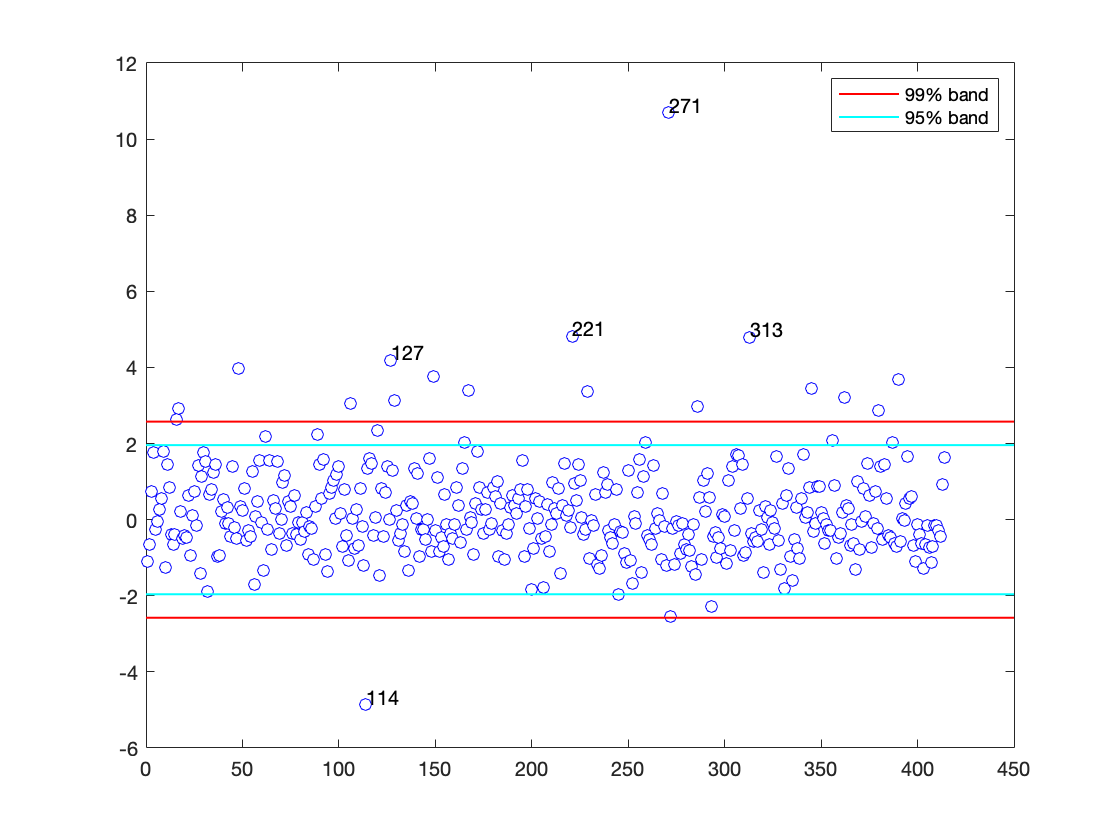

resindexplot(out,'h',h1,'conflev',conflev);

ylabel(['Breakdown point =' num2str(bdp)])
h2=subplot(2,1,2);
bdp=0.5;
[out]=Sreg(y,X,'nsamp',3000,'bdp',bdp);

Total estimated time to complete S estimate:  3.62 seconds 


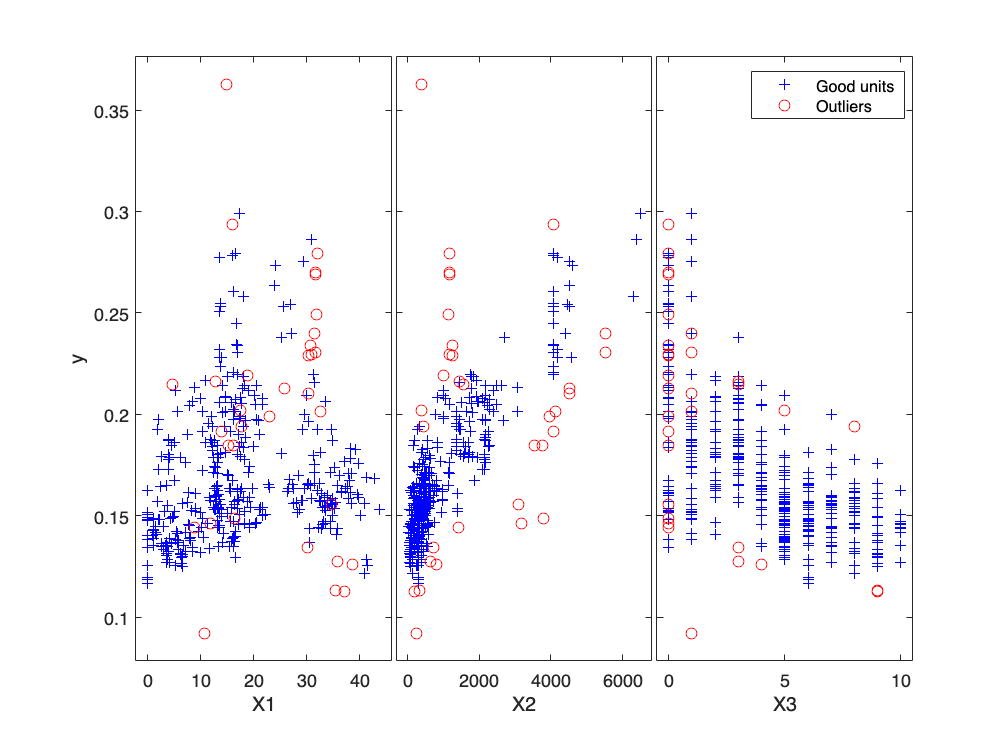

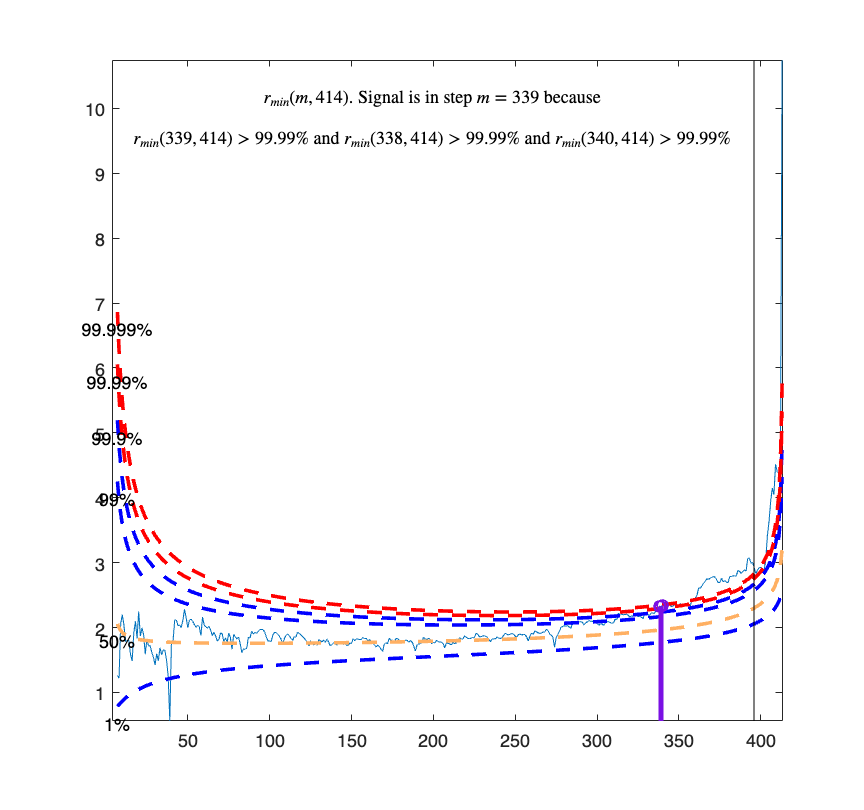

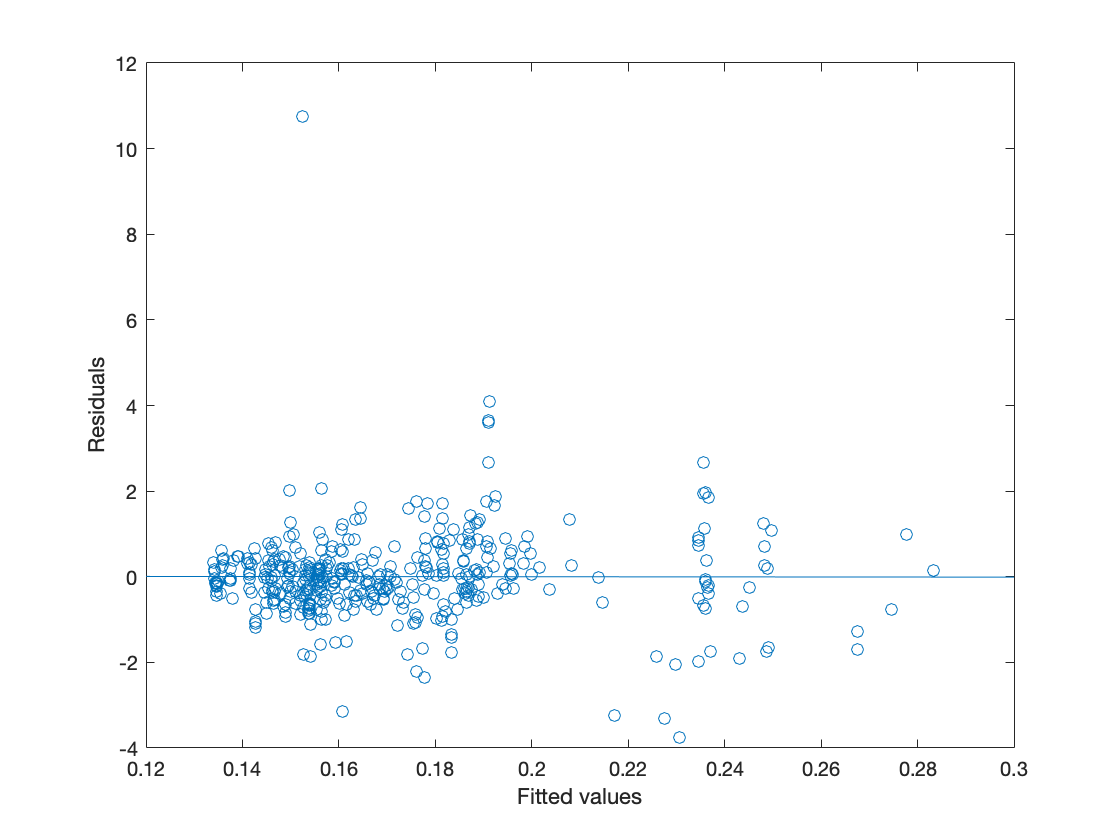

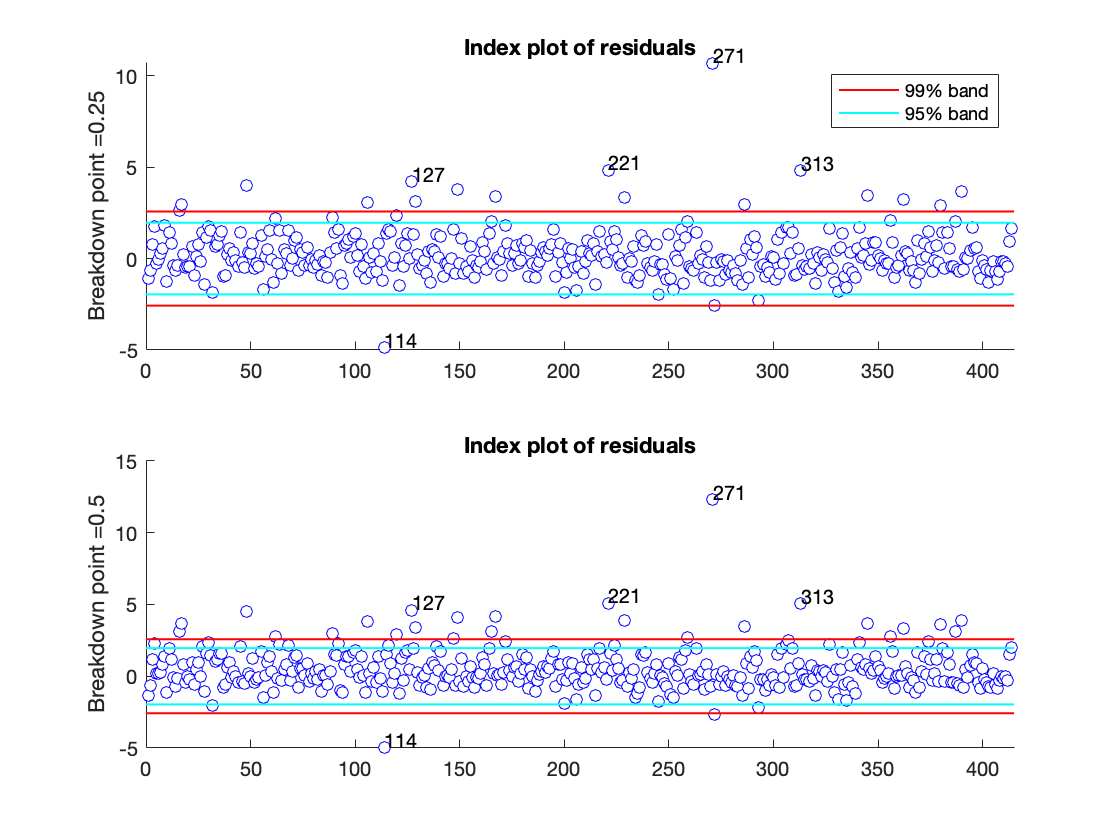

resindexplot(out,'h',h2,'conflev',conflev);
ylabel(['Breakdown point =' num2str(bdp)])
cascade;

bdp=0.5;
% due livelli di confidenza
conflev=[0.95 0.99];
[out]=Sreg(y,X,'nsamp',3000,'bdp',bdp,'yxsave',1);

Total estimated time to complete S estimate:  7.07 seconds 


Select a region to brush in the index plot of residuals


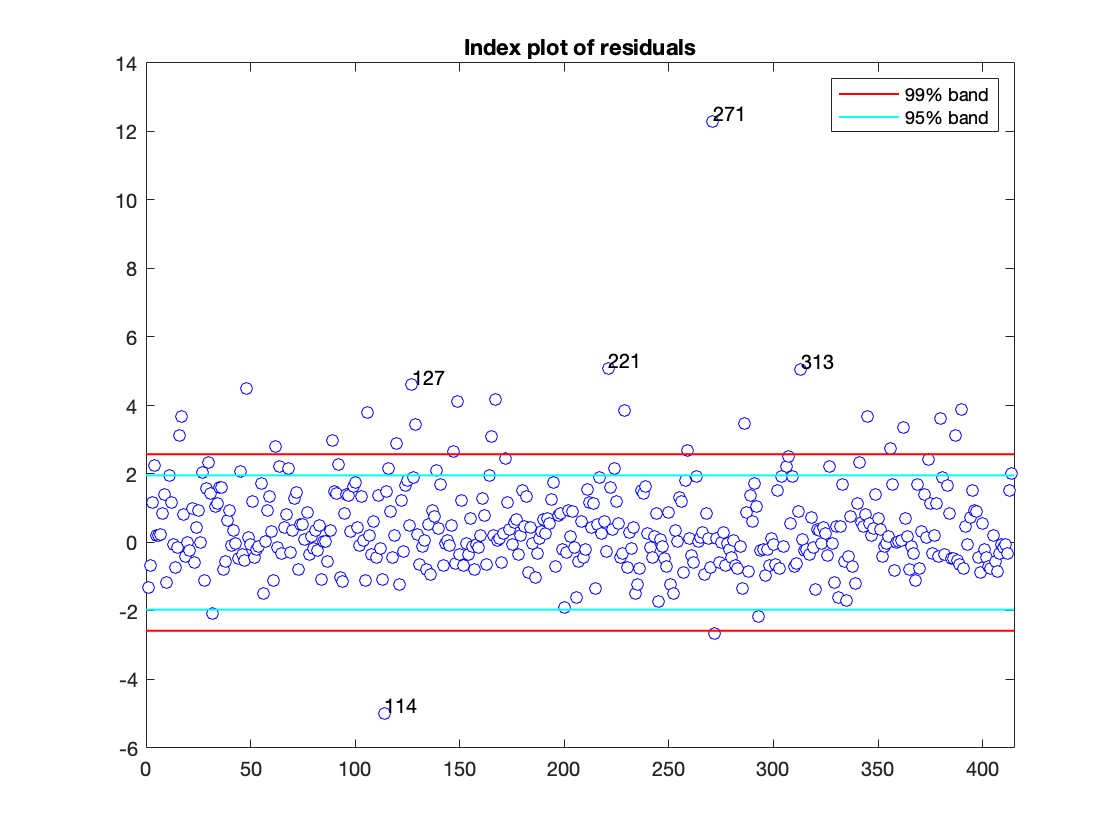

resindexplot(out,'conflev',conflev,'databrush',1);

È possibile selezionare i valori anomali dal grafico, i quali sono evidenziati dal numero di osservazione (127, 221, 313, 271, 114) e visualizzarli su un *yXplot* evidenziati in rosso.

Tramite la funzione *Sregeda *vengono calcolati gli stimatori in un modello di regressione lineare per una serie di valori di Breakdown point.

[out]=Sregeda(y,X,'nsamp',1000);

Total estimated time to complete S estimate:  3.17 seconds 
Total estimated time to complete S estimate:  1.89 seconds 
Total estimated time to complete S estimate:  1.68 seconds 
Total estimated time to complete S estimate:  1.65 seconds 
Total estimated time to complete S estimate:  1.59 seconds 
Total estimated time to complete S estimate:  1.59 seconds 
Total estimated time to complete S estimate:  1.56 seconds 
Total estimated time to complete S estimate:  4.71 seconds 
Total estimated time to complete S estimate:  1.64 seconds 
Total estimated time to complete S estimate:  1.47 seconds 
Total estimated time to complete S estimate:  1.42 seconds 
Total estimated time to complete S estimate:  1.39 seconds 
Total estimated time to complete S estimate:  1.75 seconds 
Total estimated time to complete S estimate:  1.31 seconds 
Total estimated time to complete S estimate:  1.30 seconds 
Total estimated time to complete S estimate:  1.31 seconds 
Total estimated time to complete S estim

are re-assigned to m0 or to n


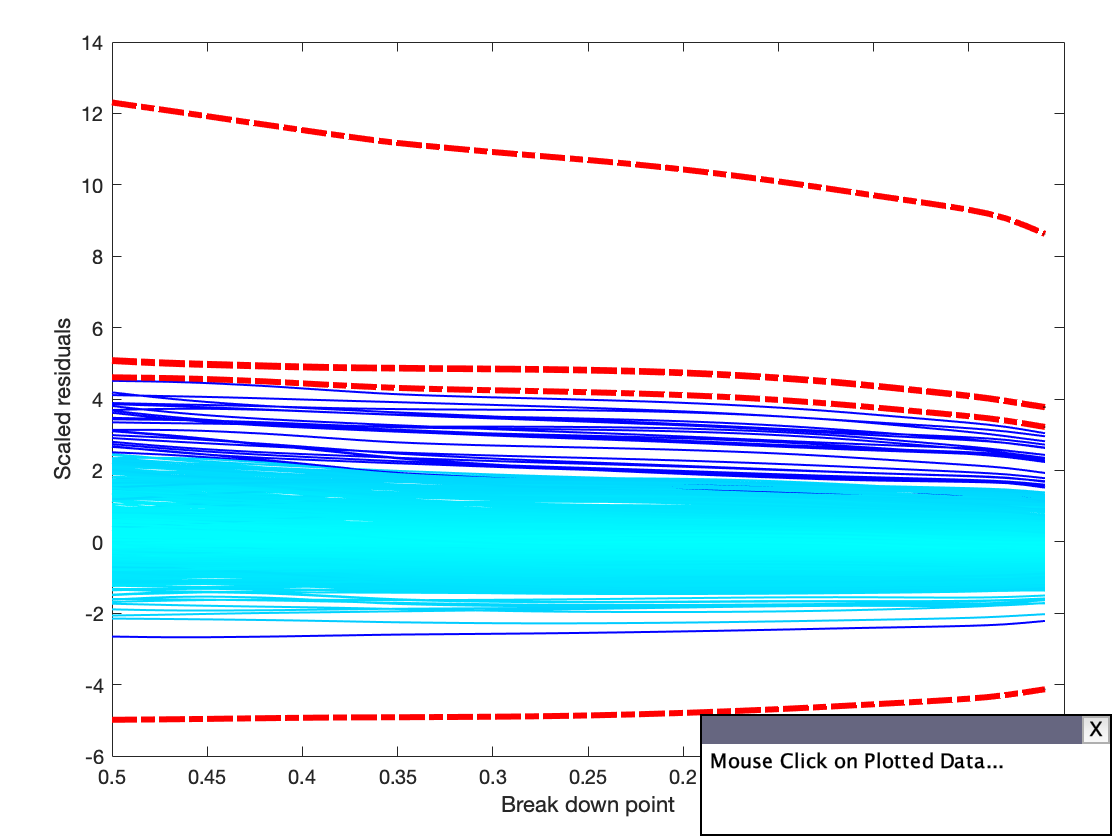


fground=struct;
sel=[127 221 313 271 114]';
fground.funit=sel;
fground.FontSize=1;

LineStyle=[ repmat({'-.'},6,1); repmat({'--'},9,1); repmat({':'},2,1)];
Color= [ repmat({'r'},6,1); repmat({'k'},9,1); repmat({'b'},2,1)];
fground.Color=Color;  % different colors for different foreground trajectories
fground.LineWidth=3;
fground.LineStyle=LineStyle;

resfwdplot(out,'fground',fground);

Il grafico mostra come variano i residui al variare del breakdown point ed è possibile analizzare ogni residuo singolarmente in ogni punto. 

% LMS using 1000 subsamples
[out]=LXS(y,X,'nsamp',10000);

Total estimated time to complete LMS:  0.48 seconds 


% Forward Search
[out]=FSReda(y,X,out.bs);

m=100
m=200
m=300
m=400


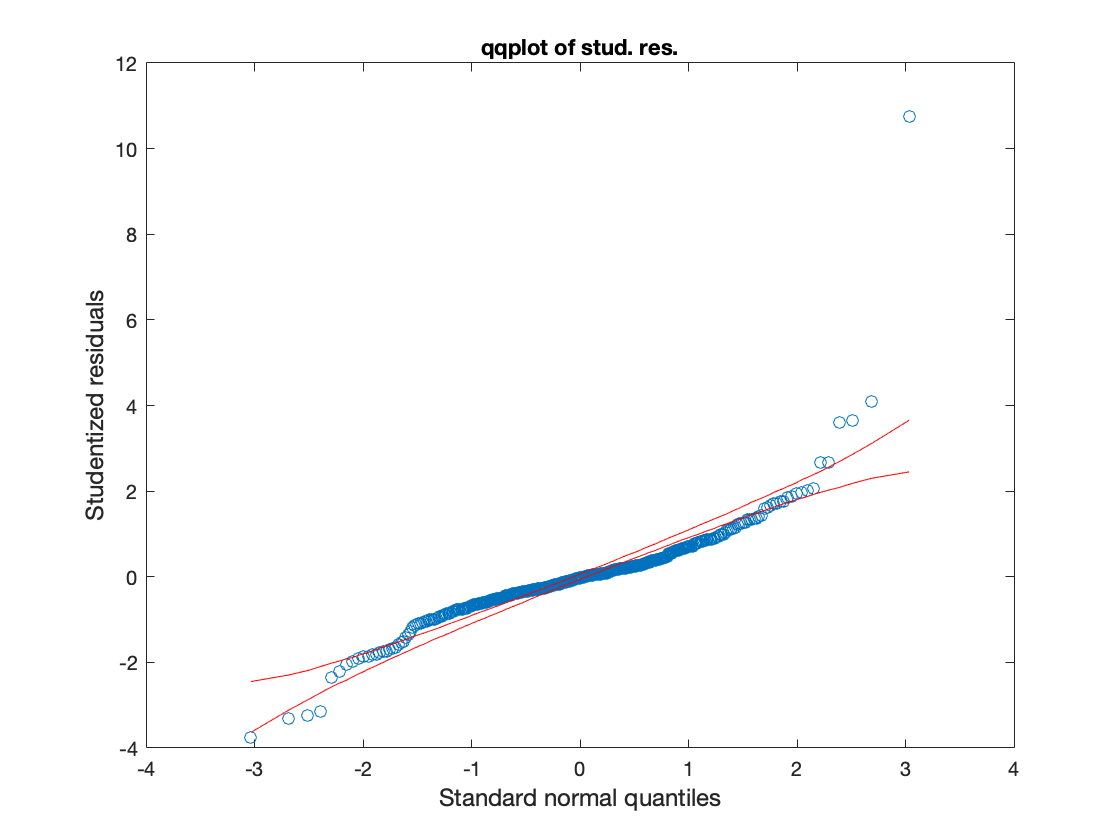

!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!
The figure you are interacting with has been deleted: PROCESS ENDED
!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!




% Create scaled squared residuals
out1=out;
% out1.RES=out.RES.^2;

datatooltip=struct;
datatooltip.SubsetLinesColor=[1 0 0];
resfwdplot(out,'datatooltip',datatooltip)

Molto utile è la funzione *resfwdplot*, la quale, grazie alle sue varie proprietà, permette di evidenziare l'ammontare di residui alla variazione di osservazioni comprese. 

% LMS 
[out]=LXS(y,X,'nsamp',10000);

Total estimated time to complete LMS:  0.42 seconds 


[out]=FSReda(y,X,out.bs);

m=100
m=200
m=300
m=400


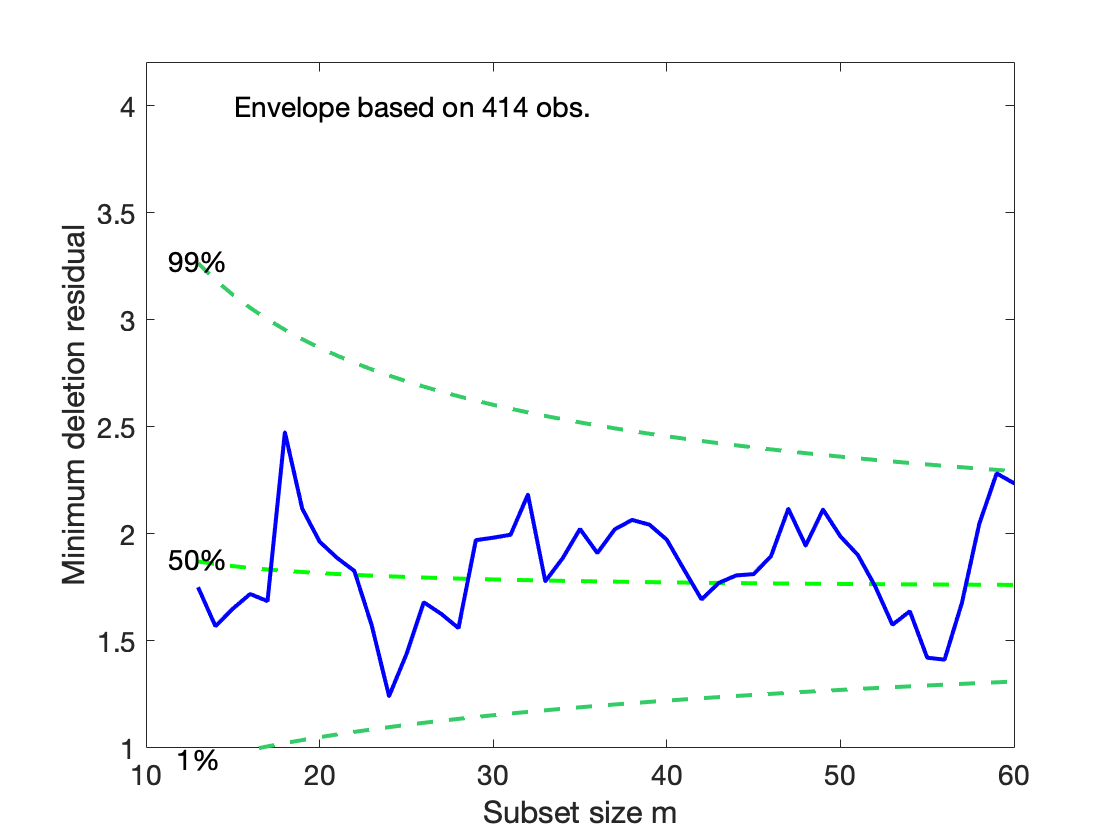

out1=out;
% Calcolare i residui su base quadratica
out1.RES=out.RES.^2;

% plot minimum deletion residual with personalized options
mdrplot(out,'ylimy',[1 4.2],'xlimx',[10 60],'FontSize',14,'SizeAxesNum',14,'lwdenv',2);


% Persistent brushing on the plot of the scaled residuals. The plot is:
fground.flabstep='';        % without labels at steps 0 and n
fground.fthresh=3.5^2;      % threshold which defines the trajectories in foreground
fground.LineWidth=1.5;      % personalised linewidth for trajectories in foreground
fground.Color={'r'};        % personalised color (red lines) for trajectories in foreground

databrush=struct;
databrush.bivarfit='';
databrush.selectionmode='Rect'; % Rectangular selection
databrush.persist='on'; % Enable repeated mouse selections
databrush.Label='on'; % Write labels of trajectories while selecting
databrush.RemoveLabels='off'; % Do not remove labels after selection
databrush.Pointer='hand'; % Hand cursor point while selecting
databrush.FlagSize='8'; % Size of the brushed points
databrush.RemoveTool='on'; % Remove yellow selection after finishing brushing
resfwdplot(out1,'fground',fground,'databrush',databrush);

Select a region to brush in the monitoring residual plot


Tramite l'impostazione "*brushing*" è possibile selezionare una moltitudine di punti e visualizzarli in un *yXplot *che rappresenti la posizione dell'osservazione nel dataset.

All'aumentare del numero di osservazioni prese in considerazione, la funzione *FSRmdr* calcola l'eliminazione minima residua e altre quantità di regressione lineare di base in ogni fase della ricerca.

[outLXS]=LXS(y,X,'nsamp',10000);

Total estimated time to complete LMS:  0.65 seconds 


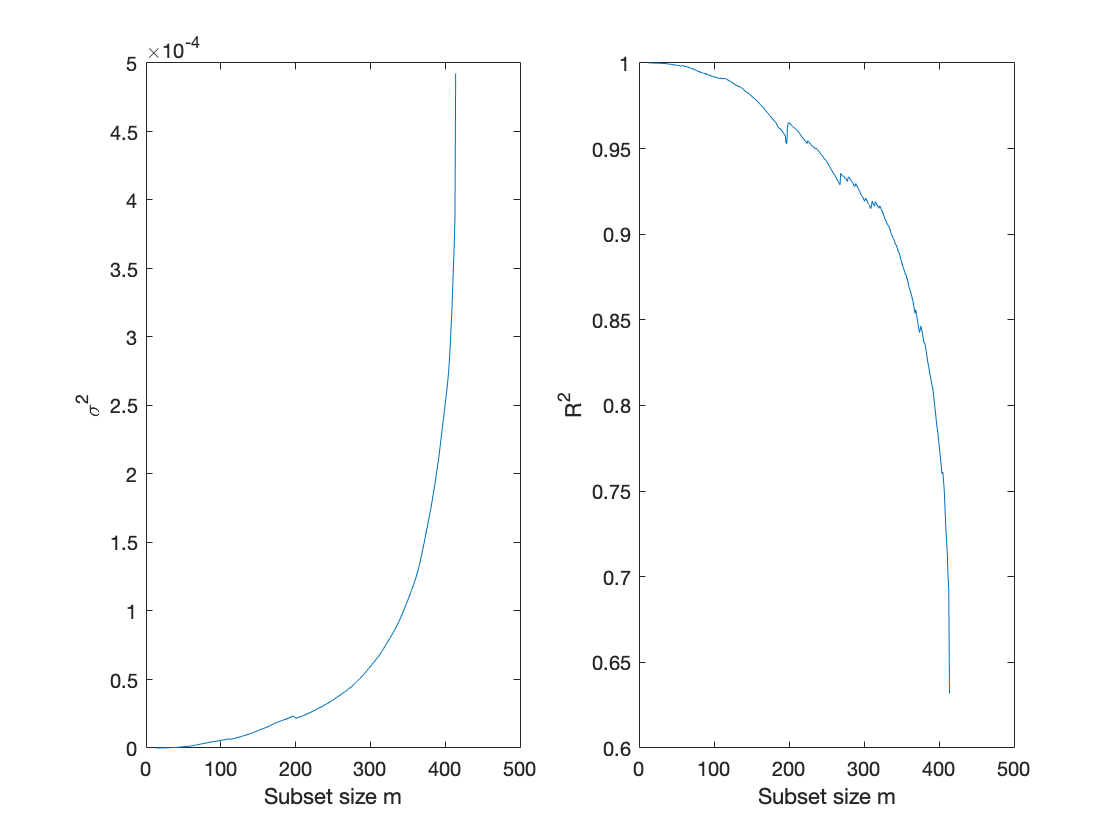

[~,~,~,Bols,S2] = FSRmdr(y1,X,outLXS.bs,'bsbmfullrank',0);

% Plot
figure;
subplot(1,2,1)
plot(S2(:,1),S2(:,2))
xlabel('Subset size m');
ylabel('\sigma^2');
subplot(1,2,2)
plot(S2(:,1),S2(:,3))
xlabel('Subset size m');
ylabel('R^2');

Dai due grafici si evince come varino il valore della varianza ($\sigma^2$) e della bontà di adattamento ($R^2$) all'aumentare delle unità osservate. Essi considerando tutto il campione assumono i valori riscontrati nell'analisi di regressione.